# Converting Script to Function

### Stimulus function

- **genFrame2Sample** creates stimulus for the design. The selection of input type is done through a `mode` input variable. 

- The function further calls **genStim** to generate a frame and then performs frame to sample conversion.

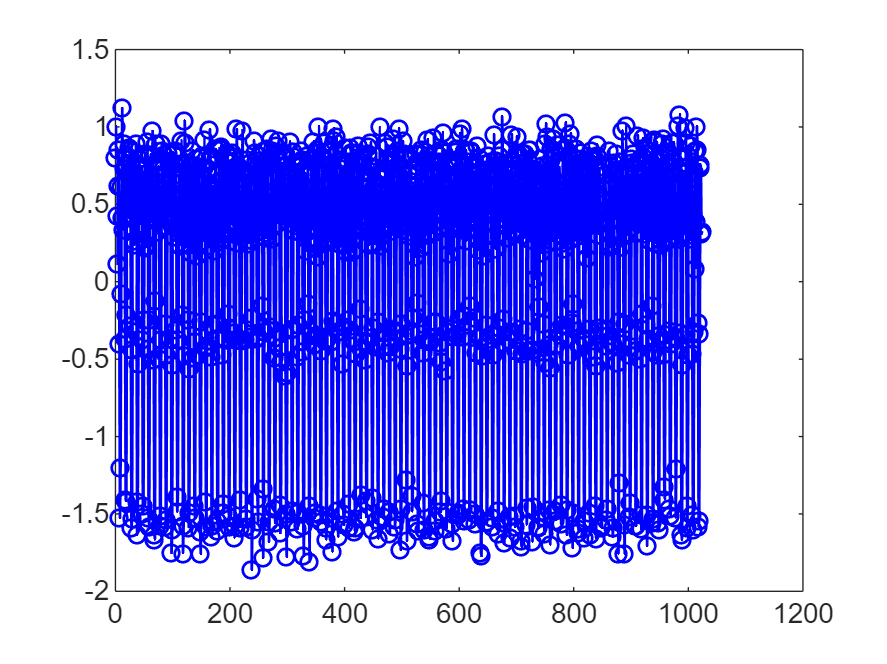

% FFT Length = 1024 

N = 1024;
Fs = 100e6;F1 = 10e6;F2 = 20e6;
mode = 2; i_ready = 1;rst = 0;

clear("genFrame2Sample");
clear("fftChecker");
clear("dutFFT");

y_fixed = zeros(1,N,'like',fi(0,1,16,13));

for i = 1:N
 [y_fixed(i),~,~,ref_frame] = genFrame2Sample(N, Fs,F1,F2,mode,i_ready,rst);
end

plot(ref_frame,'bo-', 'LineWidth', 1);

### Design function

- **dutFFT **implements the design behavior using the `dsphdl.FFT` System Object™ from the DSP HDL Toolbox™.

% DUT FFT
Yf = zeros(1,3*N);

validOut = false(1,3*N);
for loop = 1:1:3*N
    if (mod(loop, N) == 0)
        i = N;
    else
        i = mod(loop, N);
    end
    [Yf(loop),validOut(loop)] = dutFFT(y_fixed(i),(loop <= N),N);
end

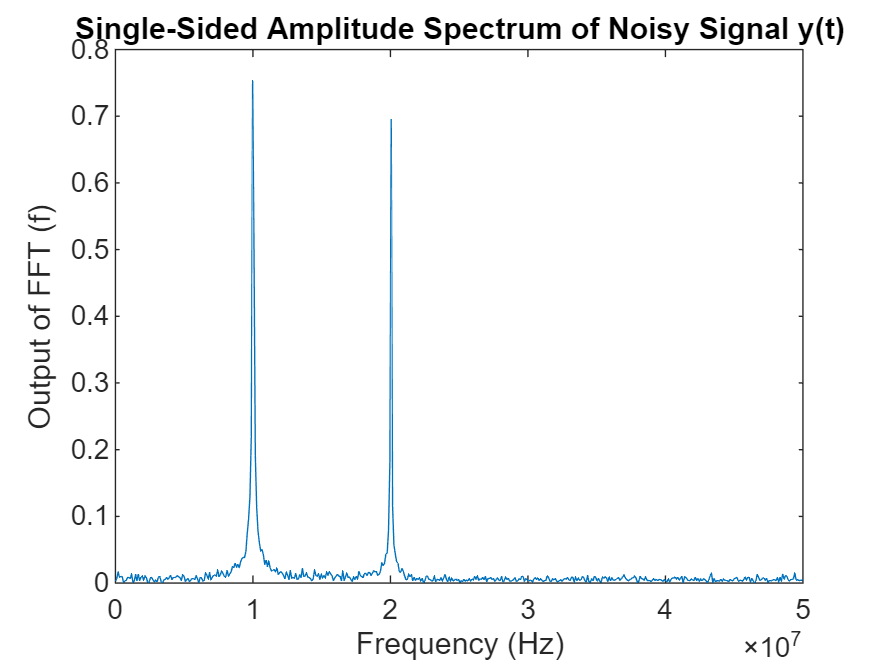

Yf = Yf(validOut == 1);
Yr =  bitrevorder(Yf);
plot(Fs/2*linspace(0,1,N/2), 2*abs(Yr(1:N/2)/N))
title('Single-Sided Amplitude Spectrum of Noisy Signal y(t)')
xlabel('Frequency (Hz)')
ylabel('Output of FFT (f)')

### Checker Function

- **fftChecker **gets input from the stimulus function and calculates the expected output. It then compares the expected output against the design output for self-checking. 

% Compare against reference 

Threshold = 10e3;
 dut_re = real(Yr);
 dut_im = imag(Yr);

for i = 1:N+2
    if (i<=N)
        valid = 1;j=i;
    else
        valid = 0;
    end
    [~,~,o_f1_exp,o_f1_dut] = fftchecker(ref_frame,dut_re(j),dut_im(j),valid,N,Fs,Threshold) ;
end

REF_CALC freq_1 = 9960937.500000 
REF_CALC freq_2 = 20019531.250000 
DUT_CALC freq_1 = 9960937.500000 
DUT_CALC freq_2 = 20019531.250000 


### DPIC generation

- **gen_dpi** provides the commands to generate SVDPI components for the stimulus and the checker. 

- Open the **gen_dpi.m** script and review it. 

% Generate DPIC model
gen_dpi

### Generating DPI-C Wrapper genFrame2Sample_dpi.c
### Generating DPI-C Wrapper header file genFrame2Sample_dpi.h
### Generating SystemVerilog module package genFrame2Sample_dpi_pkg.sv
### Generating SystemVerilog module genFrame2Sample_d

Copyright 2024 The MathWorks, Inc.